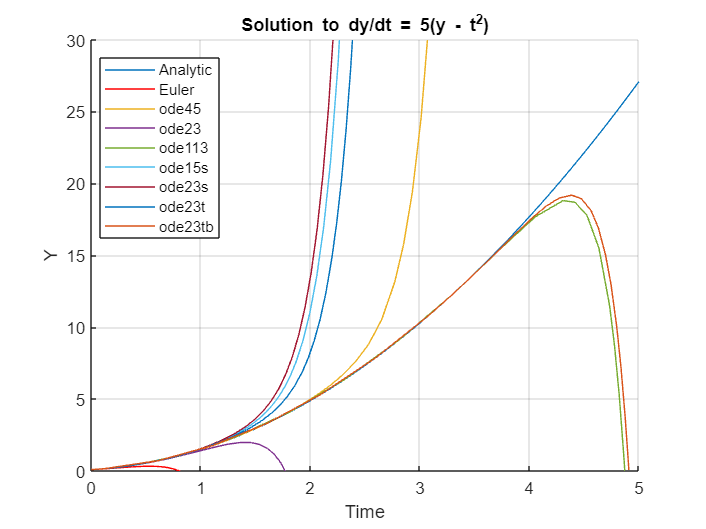

% TEP4240 SYSTEMSIMULATION  EXERCISE 1.
% Problem 1: Use of ODE-solvers on an innocent looking problem.
% Solve 
%
%      dy/dt = 5(y - t^2)
%
% for t=0 to 5 with initial condition y(0)=2/25.
% Use first order Euler method, ODE45, ODE23, ODE113, ODE15s, ODE23s, ODE23t, ODE23tb
% and compare with the analytical solution y=t^2+2t/5+2/25.
% Plot the different solutions in the same figure. 
% Can you give an explanation to the strange results?
% The following code is a beginning on problem 1, just plotting the
% analytical solution:
%%
clear all
close all
clc
tmax=5;
y0=2/25;

%Analytic solution:
ta=linspace(0,tmax);
ya=ta.^2+2*ta/5+2/25;

% Euler method
dt = 0.05;
y = y0; %initial condition
t_euler = zeros(1,tmax/dt +1);
y_euler = t_euler;
y_euler(1) = y0;
i = 1;
for t=dt:dt:tmax
    i = i+1;
    ynew = y + 5*dt*(y-t^2);
    y_euler(i) = ynew;
    t_euler(i) = t;
    y = ynew;
end


% ODE solvers
[t_ode45, Y_ode45] = ode45(@odefun1,[0 tmax],y0);
[t_ode23, Y_ode23] = ode23(@odefun1,[0 tmax],y0);
[t_ode113, Y_ode113] = ode113(@odefun1,[0 tmax],y0);
[t_ode15s, Y_ode15s] = ode15s(@odefun1,[0 tmax],y0);
[t_ode23s, Y_ode23s] = ode23s(@odefun1,[0 tmax],y0);
[t_ode23t, Y_ode23t] = ode23t(@odefun1,[0 tmax],y0);
[t_ode23tb, Y_ode23tb] = ode23tb(@odefun1,[0 tmax],y0);


figure(1)
title('Solution to dy/dt = 5(y - t^2)')
axis([0 tmax 0 30])
xlabel('Time')
ylabel('Y')
grid
hold on
plot(ta,ya,t_euler,y_euler,'r-',t_ode45,Y_ode45,t_ode23, Y_ode23,t_ode113, ...
    Y_ode113, t_ode15s, Y_ode15s,t_ode23s, Y_ode23s,t_ode23t, Y_ode23t, ...
    t_ode23tb, Y_ode23tb)
legend('Analytic','Euler', ...
    'ode45','ode23','ode113','ode15s','ode23s','ode23t','ode23tb', ...
    'Location','Best')
hold off

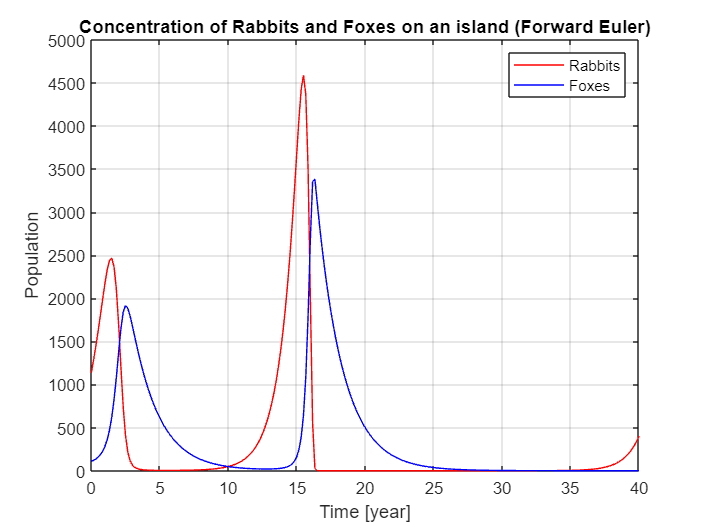





% Problem 2: Population balance Rabbits/Foxes
% We model the concentration of Rabbits (R) and Foxes (F) on an island:
% 
%     dR/dt = aR - bRF
%     dF/dt = -cF + dRF
%
% where a,b,c and d are constants. We seek the solution plotted for 40 years 
% forward in time. The task is:

% 2a)  Solve using forward Euler scheme.
clear all   
clc

% Constants (Scaled so that the time unit is 1 year):
a = 1.0;
b = 0.002;
c = 0.5;
d = 0.001;
e = 0.001;
f = 0.001;
g = 0.1;
h = 0.001;
i = 0.001;
tmax = 40.;
dt = 1/6;

% Initial conditions:
R = 1000.0;
F = 100.0;


a_t = zeros(1,ceil(tmax/dt));
a_R = zeros(1,ceil(tmax/dt));
a_F = zeros(1,ceil(tmax/dt));

% Main loop:
j = 0;
for t = 0:dt:tmax
    j = j+1;
    Rnew = R + dt*(a*R-b*R*F);
    Fnew = F + dt*(-c*F + d*R*F);
    a_t(j) = t;
    a_R(j) = Rnew;
    a_F(j) = Fnew;
    R = Rnew;
    F = Fnew;

end

plot(a_t,a_R,'r-', a_t,a_F,'b-');
legend('Rabbits','Foxes')
title('Concentration of Rabbits and Foxes on an island (Forward Euler)')
axis([0 tmax 0 1000*5])
xlabel('Time [year]')
ylabel('Population')
grid

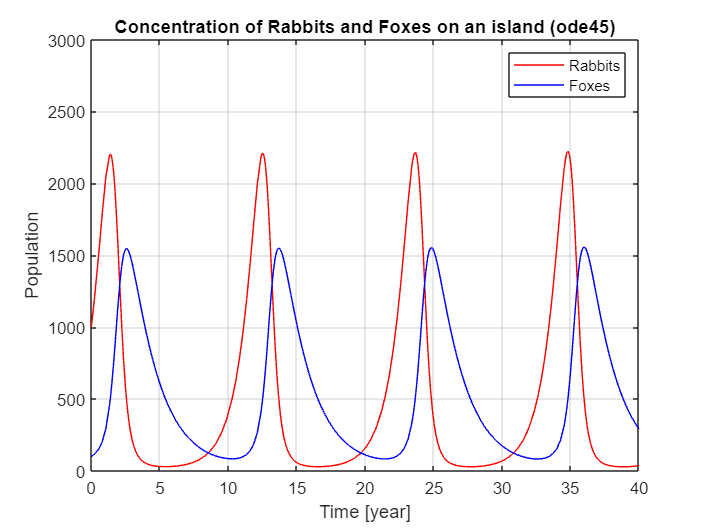




% 2b)  Solve using ODE45.

[t,Y] = ode45(@odefun2b,[0 40],[1000 100]);
b_R = Y(:,1);
b_F = Y(:,2);
plot(t,b_R,'r-', t,b_F,'b-');
legend('Rabbits','Foxes')
title('Concentration of Rabbits and Foxes on an island (ode45)')
axis([0 40 0 1000*3])
xlabel('Time [year]')
ylabel('Population')
grid

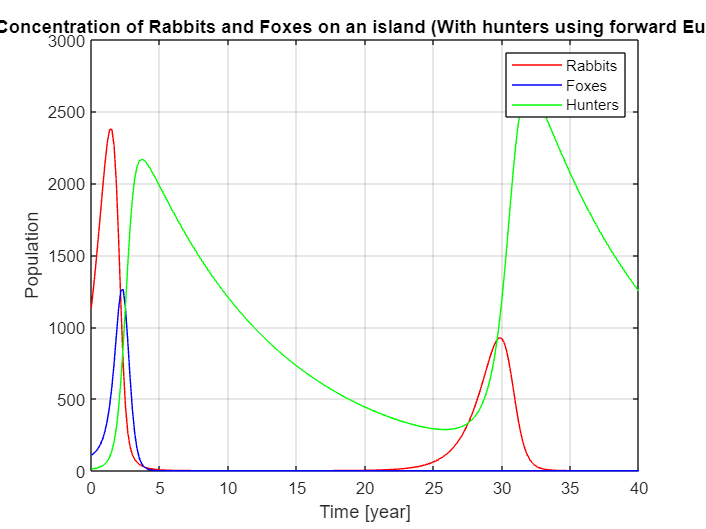




% 2c)  Add Hunters (H) on the island so that the model now becomes
% 
%     dR/dt = aR - bRF - eRH
%     dF/dt = -cF + dRF - fFH
%     dH/dt = -gH + hRH + iFH
%
% where e,f,g,h and i are new constants.

R = 1000.0;
F = 100.0;
H = 10.0;

c_euler_t = zeros(1,ceil(tmax/dt));
c_euler_R = zeros(1,ceil(tmax/dt));
c_euler_F = zeros(1,ceil(tmax/dt));
c_euler_H = zeros(1,ceil(tmax/dt));

% Main loop:
j = 0;
for t = 0:dt:tmax
    j = j+1;
    Rnew = R + dt*(a*R-b*R*F-e*R*H);
    Fnew = F + dt*(-c*F + d*R*F-f*F*H);
    Hnew = H + dt*(-g*H + h*R*H + i*F*H);
    c_euler_t(j) = t;
    c_euler_R(j) = Rnew;
    c_euler_F(j) = Fnew;
    c_euler_H(j) = Hnew;
    R = Rnew;
    F = Fnew;
    H = Hnew;
end


plot(c_euler_t,c_euler_R,'r-', c_euler_t,c_euler_F,'b-',c_euler_t,c_euler_H,'g-');
legend('Rabbits','Foxes','Hunters')
title('Concentration of Rabbits and Foxes on an island (With hunters using forward Euler)')
axis([0 tmax 0 1000*3])
xlabel('Time [year]')
ylabel('Population')
grid

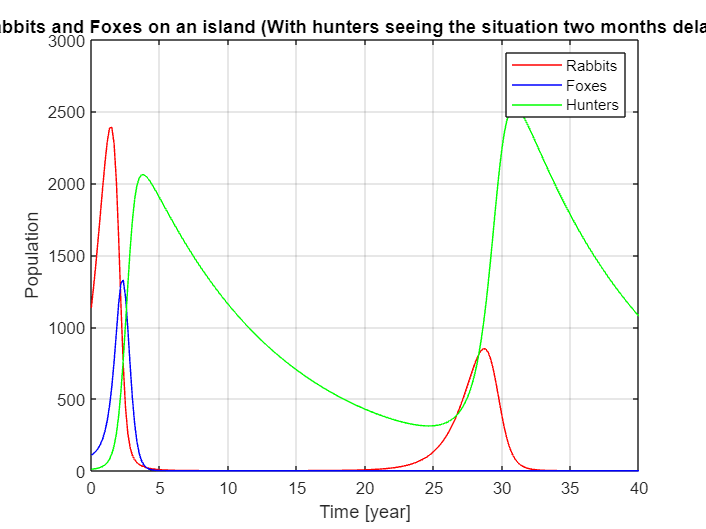




% 2d)  Adjust the time for hunters so that they see the Rabbit/fox/hunter-situation
%      2 months later. (Tip: Use Euler, not ODE45, thats rather tricky)
%

dt = 1/6;

% Initial conditions:
R = 1000.0;
F = 100.0;
H = 10.0;

c_euler_t = zeros(1,ceil(tmax/dt));
c_euler_R = zeros(1,ceil(tmax/dt));
c_euler_F = zeros(1,ceil(tmax/dt));
c_euler_H = zeros(1,ceil(tmax/dt));
% Main loop:  "dt" = two months
j = 0;
for t = 0:dt:tmax
    j = j+1;
    Rnew = R + dt*(a*R-b*R*F-e*R*H);
    Fnew = F + dt*(-c*F + d*R*F-f*F*H);

    if t == 0
        Hnew = H;
    else
        Hnew = H + dt*(-g*H + h*c_euler_R(j-1)*H + i*c_euler_F(j-1)*H);
    end
    
    c_euler_t(j) = t;
    c_euler_R(j) = Rnew;
    c_euler_F(j) = Fnew;
    c_euler_H(j) = Hnew;
    R = Rnew;
    F = Fnew;
    H = Hnew;
end


plot(c_euler_t,c_euler_R,'r-', c_euler_t,c_euler_F,'b-',c_euler_t,c_euler_H,'g-');
legend('Rabbits','Foxes','Hunters')
title('Concentration of Rabbits and Foxes on an island (With hunters seeing the situation two months delay using forward Euler)')
axis([0 tmax 0 1000*3])
xlabel('Time [year]')
ylabel('Population')
grid on